% Initializing script
clc, clf, clear

% Reference motor values
P_c_ref = 206.429E+05;  % chamber pressure (Pa)
A_t_ref = 0.0602;   % throat area (m2)
A_e_ref = 4.1548;   % exit area (m2)

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i), A_t_ref, A_e_ref]);
    total_mass_A_t(i) = calc_objective([P_c_ref, A_t(i), A_e_ref]);
    total_mass_A_e(i) = calc_objective([P_c_ref, A_t_ref, A_e(i)]);
end

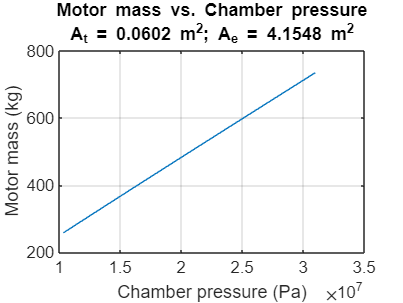

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

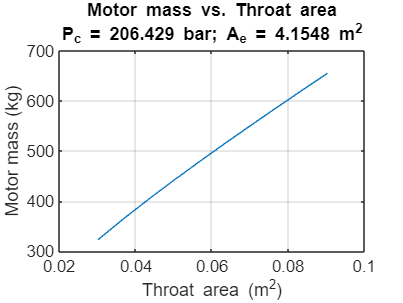


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

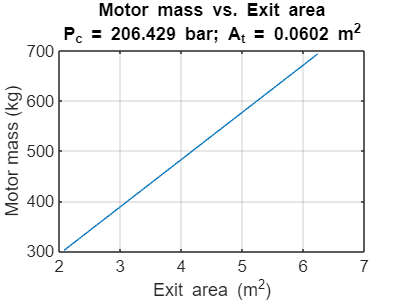


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            total_mass_val(i, j, k) = calc_objective([P_c(i), A_t(j), A_e(k)]);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints([P_c(i), A_t(j), A_e(k)]);
        end
    end
end

Error using  .* 
Arrays have incompatible sizes for this operation.

Error in Denormalize (line 6)
x=ref.*x;

Error in calc_constraints (line 3)
 x=Denormalize(x);

Related docume

% Example plot
clf
i = 2;
contourf(ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(total_mass_val(:, :, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [P_c(1), A_t(1), A_e(1)];
ub = [P_c(length(P_c)), A_t(length(A_t)), A_e(length(A_e))];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp','Diffminchange',1e-3,'Diffmaxchange',5e-1,'Tolx',1e-12,'Tolcon',1e-6);

for i = 2:7
    x0 = [P_c(i), A_t(i), A_e(i)]
    if i==2
    [x0,lb,ub]=normalize(x0,lb,ub);
    else
        x0=normalize(x0,lb,ub);
    end
    [x, fval, exitflag, output, lambda] = fmincon(@(x0)calc_objective_sens(x0), x0, ...
        A, b, Aeq, beq, lb, ub, @(x0)calc_constraints(x0), options)
    fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f', x(1), x(2), x(3))
end
